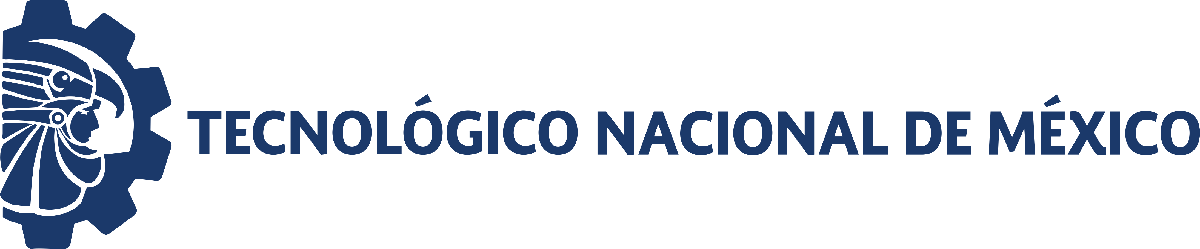                                 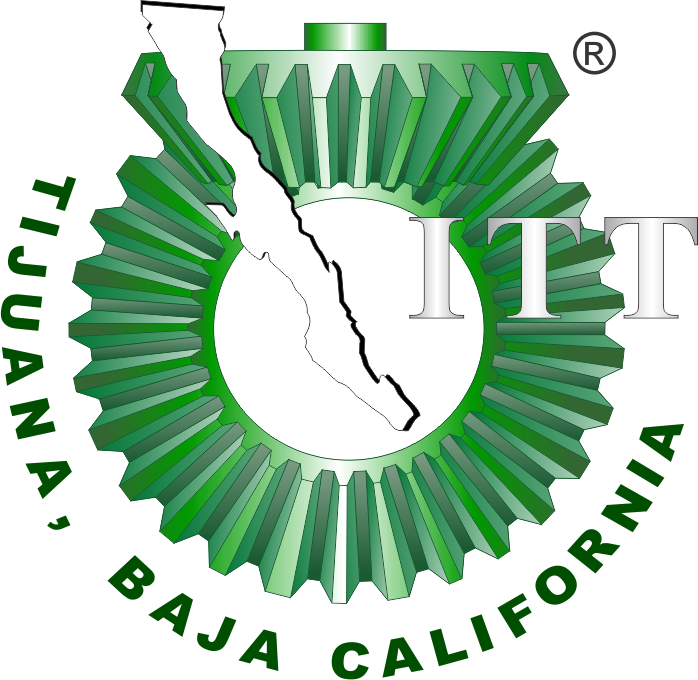

# Práctica 1: Diseño de Controladores

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

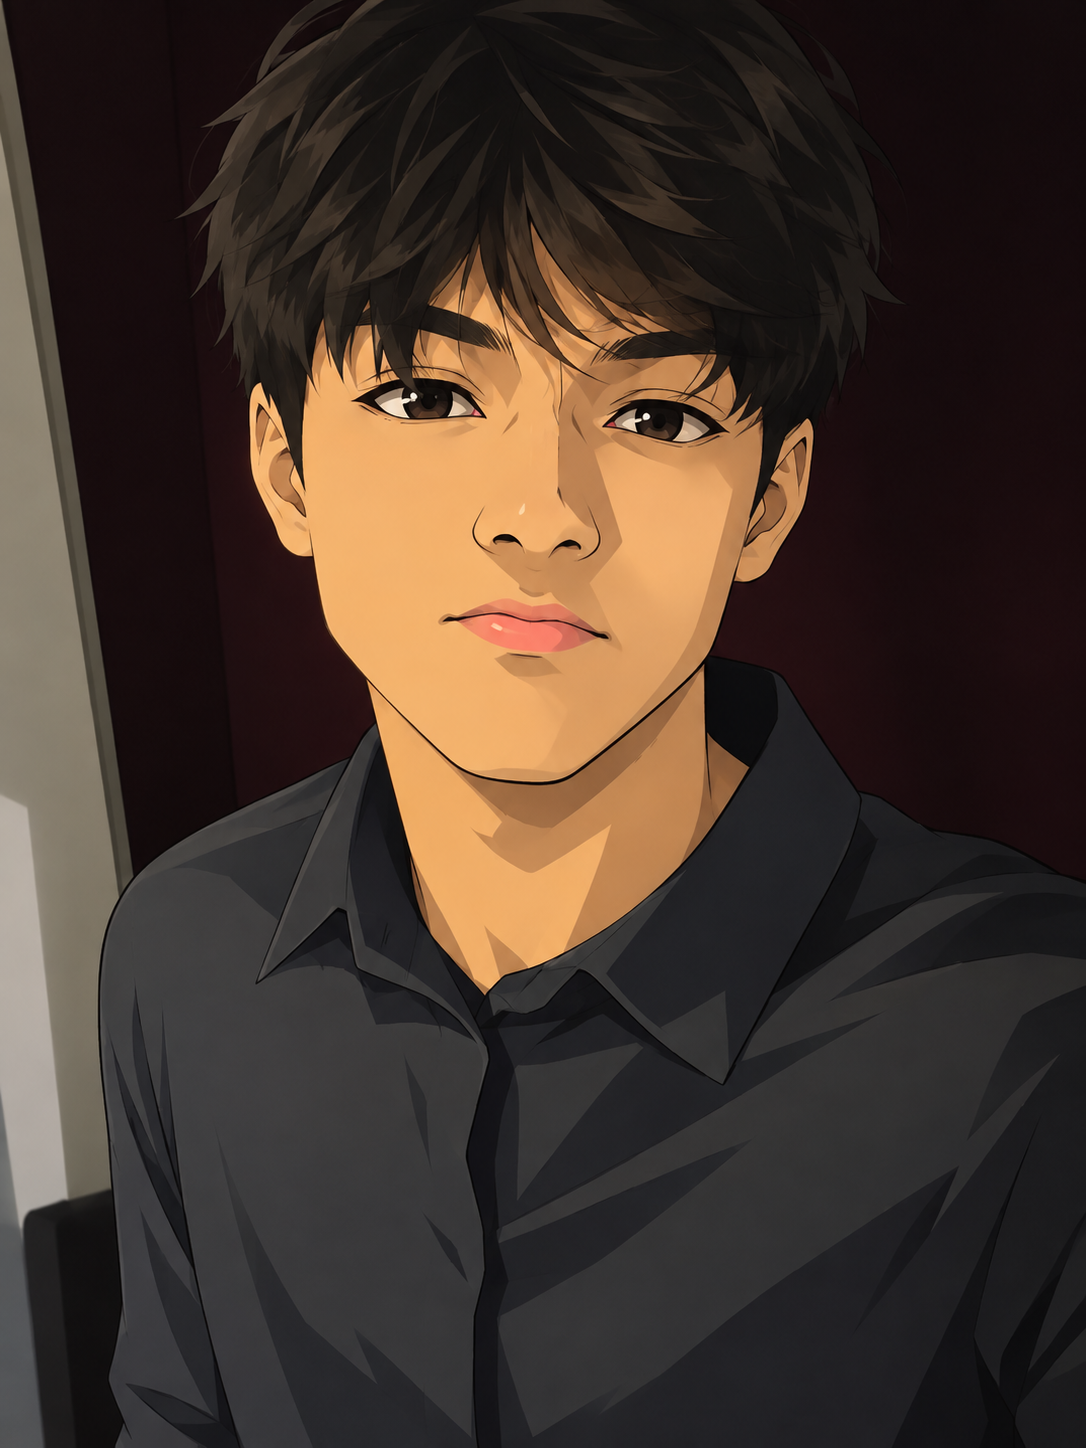

Nombre del alumno: Diego Perez Garcia

Número de control: 23212635

Correo institucional: l23212635**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system("FUNCION")
parameters.StopTime = '10'

parameters = struct with fields:
    StopTime: '10'


parameters.Solver = 'ode15s'

parameters = struct with fields:
    StopTime: '10'
      Solver: 'ode15s'


parameters.MaxStep = '1e-3'

parameters = struct with fields:
    StopTime: '10'
      Solver: 'ode15s'
     MaxStep: '1e-3'


% set_param('FUNCION/Vs(t): CE/Vs','1-D array'):


## Respuesta al escalón

set_param('FUNCION/S1','sw','1')
set_param('FUNCION/Ve(t)','sw','1')
x1 = sim('FUNCION',parameters);

Found algebraic loop that contains: 
FUNCION/Vs(t): EID/1//3R
FUNCION/Vs(t): EID/R
FUNCION/Vs(t): EID/L
FUNCION/Vs(t): EID/Derivative
FUNCION/Vs(t): EID/Add
FUNCION/Vs(t): EID/1//2R
FUNCION/Vs(t): EID/R1
FUNCION/Vs(t): EID/Add2 (algebraic variable)
FUNCION/V

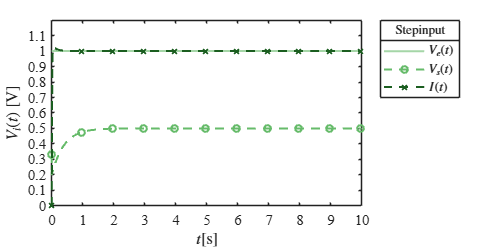

plotsignals(x1.tout,x1.Ve,x1.Vs,x1.PID,'Step')

## Respuesta al impulso

set_param('FUNCION/S1','sw','0')
set_param('FUNCION/Ve(t)','sw','1')
x2 = sim('FUNCION',parameters);

Found algebraic loop that contains: 
FUNCION/Vs(t): EID/1//3R
FUNCION/Vs(t): EID/R
FUNCION/Vs(t): EID/L
FUNCION/Vs(t): EID/Derivative
FUNCION/Vs(t): EID/Add
FUNCION/Vs(t): EID/1//2R
FUNCION/Vs(t): EID/R1
FUNCION/Vs(t): EID/Add2 (algebraic variable)
FUNCION/V

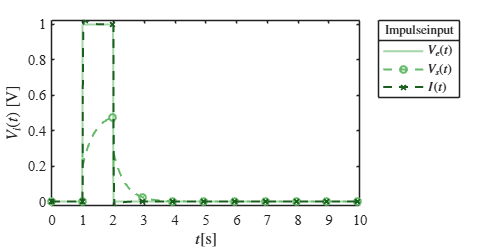

plotsignals(x2.tout,x2.Ve,x2.Vs,x2.PID,'Impulse')

## Respuesta a la rampa

set_param('FUNCION/S2','sw','1')
set_param('FUNCION/Ve(t)','sw','0')
x3 = sim('FUNCION',parameters);

Found algebraic loop that contains: 
FUNCION/Vs(t): EID/1//3R
FUNCION/Vs(t): EID/R
FUNCION/Vs(t): EID/L
FUNCION/Vs(t): EID/Derivative
FUNCION/Vs(t): EID/Add
FUNCION/Vs(t): EID/1//2R
FUNCION/Vs(t): EID/R1
FUNCION/Vs(t): EID/Add2 (algebraic variable)
FUNCION/V

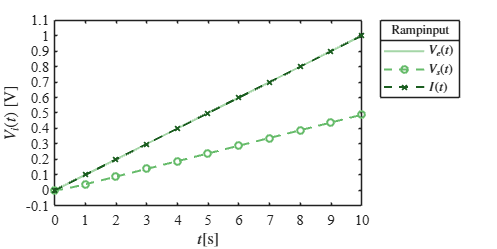

plotsignals(x3.tout,x3.Ve,x3.Vs,x3.PID,'Ramp')

## Respuesta a la función sinusoidal

set_param('FUNCION/S2','sw','0')
set_param('FUNCION/Ve(t)','sw','0')
x4 = sim('FUNCION',parameters);

Found algebraic loop that contains: 
FUNCION/Vs(t): EID/1//3R
FUNCION/Vs(t): EID/R
FUNCION/Vs(t): EID/L
FUNCION/Vs(t): EID/Derivative
FUNCION/Vs(t): EID/Add
FUNCION/Vs(t): EID/1//2R
FUNCION/Vs(t): EID/R1
FUNCION/Vs(t): EID/Add2 (algebraic variable)
FUNCION/V

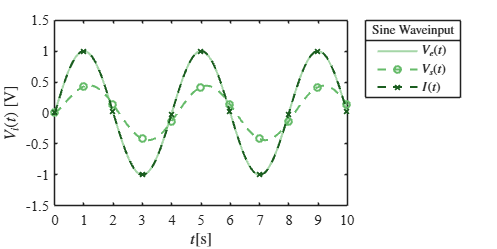

plotsignals(x4.tout,x4.Ve,x4.Vs,x4.PID,'Sine Wave')

## Funcion: Respuestas de la simulacion

function plotsignals(t,Ve,Vs,PID,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off;box on;
    clr1 = [165,214,167]/255;
    clr2 = [102,187,106]/255;
    clr3 = [27,94,32]/255;
    order = [clr1;clr2;clr3];colororder(order)


plot(t,Ve,'-',t,Vs,'--o',t,PID,'--x','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1e3:length(t));
L = legend('$V_e(t)$','$V_s(t)$','$I(t)$');
set(L,'interpreter','latex','location','northeastoutside','orientation','vertical')
title(L,[signal,'input'])

xlabel('$t$[s]','interpreter','latex')
ylabel('$V_i(t)$ [V]','interpreter','latex')

xlim([0 10]); xticks(0:1:10)

if signal == "Step"
    ylim([0 1.2]); yticks(0:0.1:1.1)
elseif signal == "Implulse"
    ylim([-0.2 1.2]); yticks(-0.2:0.1:1.1)
elseif signal == "Ramp"
    ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)
elseif signal == "Sinusoidal"
    ylim([-1.2 1.2]); yticks(-1.2:0.2:1.2)
end

exportgraphics(gcf,[signal,'_matlab.pdf'],'ContentType','vector')
end